clear all, close all, clc

############### ############### ############### ###############

## HW06-1

### (a)

For this problem, let's do the line-source trick.

we know, here


$$\phi^0 =\int_0^L \frac{S_l }{4\pi \ {\left(x^2 +h^2 \right)}}\mathcal{\ }dx$$


    ${\phi \;}^0$ = flux density from line source; $S_l =$ line source activity [#/s.cm]

The above equation reduces to, for the problem, like this-


$$\phi^0 =\frac{S_l }{4\pi h}\tan^{-1} {\left(\frac{l}{h}\right)}$$


Or, $\phi^0 =\frac{S_l }{4\pi h}\tan^{-1} {\left(\frac{2\pi r\;}{h}\right)}$

Now, given,

E = 1;                  % ph' energy; MeV
r = 1*100;              % radius; cm
h = 1*100;              % height; cm
Sp = 1e5*1e9;           % source activity; Bq
Sl = Sp /(2*pi*r)       % activity, line source; Bq/cm

Sl = 1.5915e+11

So, we have, fromt he equation deduced-

  C = atan(2*pi*r/h)    % a constant

C = 1.4130

ph0 = Sl /(4*pi*h) *C   % flux density, vaccumm, uncollided; #/cm^2.s

ph0 = 1.7895e+08

Now, let's consider the flux-attenuation for water media

Here, from Textbook AC-TC7, for 1 MeV photon in water-

mu_rh_w = 0.07066;          % mass interaction coeff; cm^2/g
rh_w = 1;                   % water density; g/cm^3
mu_w = mu_rh_w* rh_w        % LEAC, water; cm^-1

mu_w = 0.0707

Then, let's do the following-


$$\phi^0 =\phi_v^0 \;e^{-\mu r\;\;} \;$$


ph0_w = ph0 *exp(-mu_w*r)   % flux, unc', water; #/cm^2.s

ph0_w = 1.5276e+05

(Ans)

### (b)

Now, let's use the following equation-


$${\mathcal{R}}_k =1\ldotp 602\times {10}^{-10} \;E\;\frac{\mu_{\textrm{tr}} }{\rho \;}$$
    

    Here, ${\mathcal{R}}_k =$ kerma response function

From Textbook AC-TC7, we have-

mu_tr_rh_w = 0.0311;        % E-transfer coeff', water; cm^2/g
R_kw = 1.602e-10 *E *mu_tr_rh_w  % kerma RF, water; Gy.cm^2

R_kw = 4.9822e-12

Now, let's calculate the total kerma rate, for water-

K0_w = ph0_w *R_kw            % kerma rate, water; Gy/s

K0_w = 7.6110e-07

(Ans)

### (c)

Again, we get, from Textbook AC-TC7

mu_tr_rh_a = 0.02797;           % E-transfer coeff, air; cm^2/g
R_ka = 1.602e-10 *E *mu_tr_rh_a  % kerma RF, air; Gy.cm^2

R_ka = 4.4808e-12

Now, let's find teh photon flux from air. So, fromt Textbook AC-TC7

mu_rh_a = 6.353e-2;         % mass interaction coeff, air; cm^2/g
rh_a = 1.205e-3;            % air density; g/cm^3
mu_a = mu_rh_a* rh_a        % LEAC, air; cm^-1

mu_a = 7.6554e-05

Then, let's find the photon flux.

ph0_a = ph0 *exp(-mu_a*r)   % ph' flux, unc', air; #/cm^2.s

ph0_a = 1.7759e+08

So, teh kerma rate, in air-

K0_a = ph0_a *R_ka           % kerma rate, water; Gy/s

K0_a = 7.9574e-04

(Ans)

### (d)

Let's use the following formula-


$${\mathcal{R}}_x =1\ldotp 835\times {10}^{-8} \;E\;\frac{\mu_{\textrm{tr},a} }{\rho \;}$$


R_x = 1.835e-8 *mu_tr_rh_a  % exposure response func'; R.cm^2

R_x = 5.1325e-10

So, to find the exposure, we get-

X0 = R_x *ph0_a             % exposure rate; R/s

X0 = 0.0911

(Ans)

############### ############### ############### ###############

## HW06-1

Given,

d1 = 2.5*100;       % inside dia; cm
r1 = d1/2;          % inside radius; cm
d2 = 4.5*100;       % outside dia; cm
r2 = d2/2;          % outside radius; cm
t = r2 - r1         % shield thickness; cm

t = 100


A = 4000;           % source activity; Ci

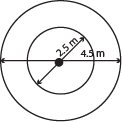

Let's use the following equation from Textbook E7.26

$D\left(P\right)=\frac{A}{r^2 }\;\Gamma \;A_f$       $D\left(P\right)=$ exposure rate; $A_f =$ attenuation factor

We know, Co-60 emits $\gamma$ of two energies; $\gamma_1 =$ 1.173 MeV; $\gamma_2 =$ 1.33 MeV

Now, from Textbook AC-TC5, we get the following for concrete

So, let's interpolate

E = [1.25, 1.5];                % MeV
mu_rh = [5.698e-2, 5.191e-2];   % cm^2/g

E1 = 1.173;             % energy of 1st g; MeV
E2 = 1.33;              % energy of 2nd g; MeV
 
mu_rh_1 = interp1(E, mu_rh, E1, 'linear','extrap') 

mu_rh_1 = 0.0585

                            % MAC, concrete; cm^2/g
mu_rh_2 = interp1(E, mu_rh, E2)

mu_rh_2 = 0.0554

Then again,

rh_c = 2.3;         % density of concrete; g/cm^3

mu_1 = mu_rh_1 * rh_c   % LEAC-1, concrete; cm^-1

mu_1 = 0.1346

mu_2 = mu_rh_2 * rh_c   % LEAC-2, concrete; cm^-1

mu_2 = 0.1273

Now, let's find the attenuation factor using the following formula-


$$A_f =y_{1\;} e^{-\mu_1 t} +y_2 e^{-\mu_2 t}$$


Now, from nuclide chart, we find the following

y1 = 0.9885;        % yield of g1
y2 = 0.0015;        % yield of g2

So, we have

A_f1 = y1* exp(-mu_1*t);         % attenuation factor
A_f2 = y2* exp(-mu_2*t);
A_f = A_f1 + A_f2 

A_f = 1.4085e-06

From Textbook T7.4, we get the value of $\Gamma \;$function

G = 1.3;            % Gamma func'; R.m^2 /Ci.h

Now, let's use the mentioned equation-

d2 = 4.5;               % outside dia; m
r2 = d2/2;              % ; m
D = A/r2^2 *G *A_f      % exposure rate; R/hr

D = 0.0014

(Ans)

############### ############### ############### ###############

## HW06-3

Given,

E = 1;              % energy of photon; MeV
Sl = 4e11;          % line-source activity; 1/m.s

Geometric options are

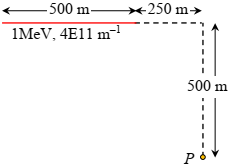  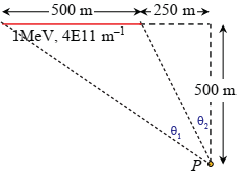

l = 500;            % line source distance; m
r = 250;            % horizontal dist' of etector; m
h = 500;            % vertical distance of detector; m

Now, let's find the angles the point makes.

th_1 = atan( (l+r)/h)       % ; rd

th_1 = 0.9828

th_2 = atan( (r)/h) 

th_2 = 0.4636

Now, let's find the necessary coefficients for the medium

From Textbook AC-C7 we get

mu_rh_w = 7.066e-2;     % MEAC, water; cm^2/g
rh_w = 1;               % density, water; g/cm^3
mu_w = mu_rh_w *rh_w    % LEAC, water; cm^-1

mu_w = 0.0707


mu_rh_a = 6.353e-2;     % MEAC, air; cm^2/g
rh_a = 1.2e-3;          % density, air; g/cm^3
mu_a = mu_rh_a *rh_a    % LEAC, air; cm^-1

mu_a = 7.6236e-05

Now, lets find the total LEAC for air. Using the following diagram-

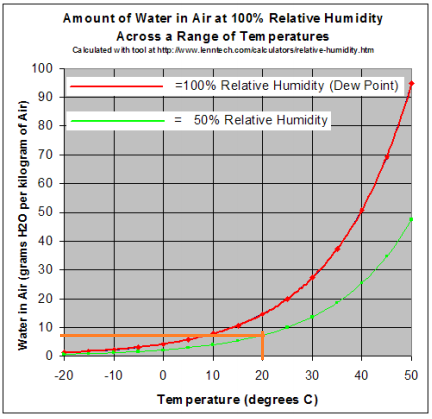

We can say, for given conditions (20 dC, 45% RH) there are 8 g of water in 1000 g of air. So-

f_w = 0.008;        % water fraction in air
f_a = 1 - f_w;      % air fraction
mu = f_a*mu_a + f_w*mu_w        % LEAC of air; cm^-1

mu = 6.4091e-04

Now, to find the uncollided dose at detector's point, let's use the following equation-$D^0 =\frac{S_l \mathcal{R}}{4\pi h}\left\lbrack F{\left(\theta_1 ,\mu h\right)}-F{\left(\theta_2 ,\mu h\right)}\right\rbrack$

Here,

h = h*100;          % vertical distance; cm
mu_h = mu*h

mu_h = 32.0453

b = mu_h;           % cm^3/g

Then, $F{\left(\theta_1 ,\mu h\right)}=F\left(0\ldotp 983,32\right)$

And, $F{\left(\theta_2 ,\mu h\right)}=F\left(0\ldotp 464,32\right)$

Let's look up that in Textbook AB-TB1, and interpolate-

Let's find the value of F for th_2, the smaller angle.

th_2;                        % the smaller angle
th_2x = [0.43633, 0.52360];     % given values about th_2
b_x = [25, 35];                % given values, abotu b
F_2_1x = [0.549, 0.472];        % given I values for th_2x(1)
F_2_1 = interp1(b_x, F_2_1x, b)

F_2_1 = 0.4948


F_2_2x = [0.465, 0.397];        % given I values for th_2x(2)
F_2_2 = interp1(b_x, F_2_2x, b)

F_2_2 = 0.4171

F_2x = [F_2_1, F_2_2];          % taking up F_2 values

%
F_2 = interp1(th_2x, F_2x, th_2)

F_2 = 0.4704

And, then let's find F for th_1, the bigger angle

th_1x = [0.87226, 1.0472];     % given values about th_1
b_x = [25, 35];                % given values, about b
F_1_1x = [0.280, 0.238];        % given I values for th_1x(1)
F_1_1 = interp1(b_x, F_1_1x, b)

F_1_1 = 0.2504


F_1_2x = [0.234, 0.199];        % given I values for th_1x(2)
F_1_2 = interp1(b_x, F_1_2x, b)

F_1_2 = 0.2093

F_1x = [F_1_1, F_1_2];          % taking up F_1 values

%
F_1 = interp1(th_1x, F_1x, th_1)

F_1 = 0.2245

Now, we know that, for response function-


$$R_x =1\ldotp 835\times {10}^{-8} \;E\;\frac{\mu_{\textrm{en}} }{\rho \;}$$


From Textbook AC-TC7, we have

mu_en_rh_a = 2.789e-2;          % MEAC, air; cm^2/g
R_x = 1.835e-8 *E*mu_en_rh_a    % exposure RF, air; R.cm^2

R_x = 5.1178e-10

So, let's find the dose/exposure


$$D^0 =\frac{S_l \mathcal{R}}{4\pi h}\left\lbrack F{\left(\theta_2 ,\mu h\right)}-F{\left(\theta_1 ,\mu h\right)}\right\rbrack$$


Sl = Sl/100;                % line-source activity; #/cm.s
h = 500*100;                % distance; cm 
    F = F_2 - F_1               % definging a const'

F = 0.2460

D0 = Sl*R_x/ (4*pi*h) *F    % exposure; R.s

D0 = 8.0143e-07

(Ans)

############### ############### ############### ###############

## HW06-4

From Textbook AC-C6

rh_l = 11.35;       % lead density; g/cm^3
rh_c = 2.3;         % concrete density; g/cm^3
mu_rh_l = 6.803e-2;     % MEAC, lead; cm^2/g
mu_rh_c = 6.369e-2;     % MEAC, conc; cm^2/g

mu_l = mu_rh_l*rh_l     % LEAC, lead; cm^-1

mu_l = 0.7721

mu_c = mu_rh_l*rh_c     % LEAC, conc; cm^-1

mu_c = 0.1565

Now, Given

l_l = 10;           % no. of MFPs of lead; optical thickness
l_c = 10;           % ...concrete
l_T = l_l + l_c     % total 

l_T = 20

As we have: $l=\mu x$     x = mean free path length

x_l = l_l/mu_l      % MFP, lead; cm

x_l = 12.9510

x_c = l_c/mu_c      % MFP, conc; cm

x_c = 63.9104

Also, given

B_c_10 = 20.7;      % exposure BF, concrete, 10 MFPs
B_c_20 = 57.7;      % exposure BF, concrete, 20 MFPs
B_l_10 = 3.37;      % exposure BF, lead, 10 MFPs
B_l_20 = 5.17;      % exposure BF, lead, 20 MFPs

### (a)

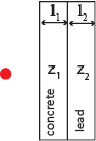

Let's use this equation-


$$B_c =\begin{array}{c}
B_2 {\left(l_1 +l_2 \right)},\ \;\;\;\;z_1 <z_2 \\
B_2 {\left(l_2 \right)}\ldotp B_1 {\left(l_1 \right)},\ \ z_1 >z_2 
\end{array}$$


Here, for this case, $z_1 <z_2$

Bc = B_c_20          % combined buildup factor

Bc = 57.7000

Then, Shielding factor-


$$\textrm{SF}=B\left\lbrack \exp \left(-\mu x\;\right)\right\rbrack$$


SF1 = Bc *exp(-l_c)      % for concrete

SF1 = 0.0026

SF2 = Bc *exp(-l_l)      % for lead

SF2 = 0.0026

SF = SF1 + SF2           % combined shielding factor

SF = 0.0052

### (b)

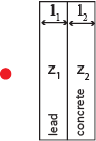

This case, $z_1 >z_2$. So-

Bc = B_l_10 *B_c_10     % combined buildup factor

Bc = 69.7590

Then, the shielding factor

SF1 = Bc *exp(-l_c)      % for concrete

SF1 = 0.0032

SF2 = Bc *exp(-l_l)      % for lead

SF2 = 0.0032

SF = SF1 + SF2           % combined shielding factor

SF = 0.0063

### (c)

The results look different because shield's order matter here. In first case, concrete was closer to source, so the buildup of photon dose was of a particular value. In the second case, lead was closer, which has higher z value, which makes the buildup higher, consequently giving a higher shielding factor.

############### ############### ############### ###############

## HW06-5

We know the follows for line source, shown in the following figure-

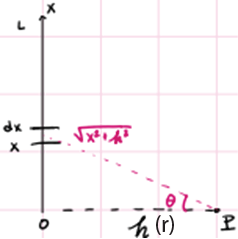


$$\phi_l^0 =\frac{S_l }{4\pi h}\tan^{-1} {\left(\frac{l}{h}\right)}$$


    $l=$ length; $h=$ height

Similarly, for poing source, we have


$$\phi_p^0 =\frac{S_p }{4\pi r^2 }$$


Where, $S_l =\frac{S_p }{l}$        $S_p =$ strength of point source [Bq]

Let, the distance is r, where, where the line's sources intensity i.t.o flux density, becomes like that of a point source.

Given,


$$|\frac{\phi_l^0 -\phi_p^0 }{\phi_p^0 }|\le 0\ldotp 01$$


Putting the values of the above equation, we have-


$$\frac{\frac{S_l }{4\pi r}\tan^{-1} {\left(\frac{l}{r}\right)}-\frac{S_p }{4\pi r^2 }}{\frac{S_p }{4\pi r^2 }}\le 0\ldotp 01$$


Or, $\frac{S_l r\;\tan^{-1} {\left(\frac{l}{r}\right)}-S_p }{S_p }\le 0\ldotp 01$

Or, $\frac{r\;\tan^{-1} {\left(\frac{l}{r}\right)}-l}{l}\le 0\ldotp 01$            As, $S_l \;l=S_p$

Or, $r\;\tan^{-1} {\left(\frac{l}{r}\right)}\le 1\ldotp 01\;l$

Or, $\frac{l}{r}\le \tan \left(1\ldotp 01\;\frac{l}{r}\right)$

Or, $x-\tan \left(1\ldotp 01x\right)\le 0$             Forming a classic inequality

Now, the analogous equation is-


$$x-\tan \left(1\ldotp 01x\right)=0$$


Also, $x=\frac{l}{r}<1$, as the point's distance has to be far greater than l' lenth 

Let's solve it,

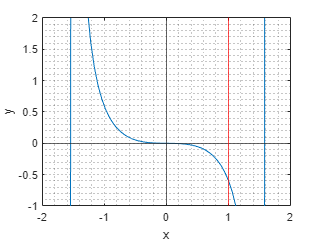

x = linspace(-2,4,101);
xr = deg2rad(x);
y = x - tan(1.01*x);

figure(1)
plot(x,y), grid minor
xline(0), yline(0)      % showing axes
xline(1,'r')            % x's limit
ylim([-1, 2])         % setting y's limit
xlabel('x'); ylabel('y')

From the above figure, to satisfy the inequality we found that the value of x has to be around 0.4. So, 


$$x=\frac{l}{r}=0\ldotp 4$$


Or, $r=2\ldotp 5l$

So, the line source could be approximated as point source when the point's distance is almost 2.5 times more than length of the line source.

(Ans)